# First Question 

`part (a),(b),(c):( first for input1 and then for input2 ) `

`using Newton interpolant ...`

`here is the Newton polynomial for the Given inputs`

input1 = zeros(4,2);
input2 = zeros(7,2);
input1(:,1) = linspace(1,4,4); % ((step per level) or h) is = 0.5
input2(:,1) = linspace(1,4,7); % ((step per level) or h) is = 0.5
input1(:,2) = log(input1(:,1))/log(2);
input2(:,2) = log(input2(:,1))/log(2);
% now lets see the spline and the NewtonPolynomial
% First I draw the main fucntion log ( x in 2 basis)
domain = linspace(1,4,100);
figure
plot(domain,log(domain)/log(2),'g*')
hold on
splines = splineDraw(input1);

dimension = 4

hold on
syms x
f(x) = giveMeNewtonPolynomial(input1);

deltaMatrix =     1.0000         0         0         0         0
    2.0000    1.0000    1.0000         0         0
    3.0000    1.5850    0.5850   -0.2075         0
    4.0000    2.0000    0.4150   -0.0850    0.0409


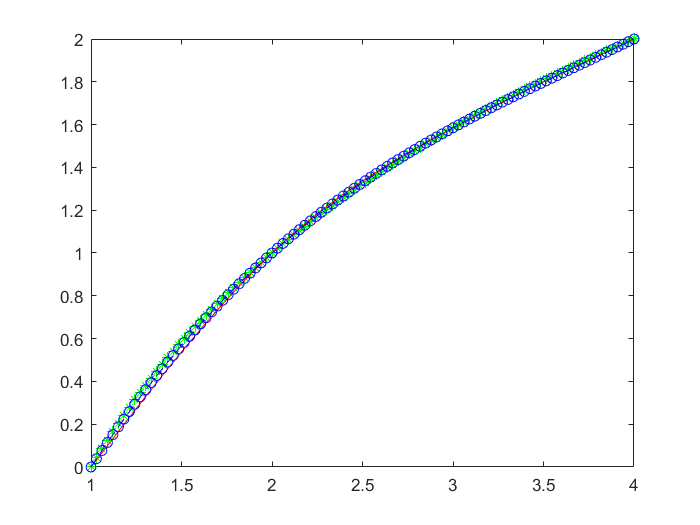

plot(domain,f(domain),'b--o');

% green is for the main function
% red is for the spline approximation
% blue is for the polynomial approximation 

# `part D for first input(input1)`

`calculate the function in x = 0.5 & x = 5;`

% calculation via polynomial 
figure
polyCal = [0.5,f(0.5);5,f(5)]

$$polyCal = \left(\begin{array}{cc} \frac{1}{2} & -\frac{844211458418370437}{1152921504606846976}\\ 5 & \frac{44859905450327617}{18014398509481984} \end{array}\right)$$

stem(polyCal(:,1),polyCal(:,2),'filled');
hold on 
syms x
before(x) = splines(1,1);
after(x) = splines(3,1);
splineCal = [0.5,before(0.5);5,after(5)]

$$splineCal = \left(\begin{array}{cc} \frac{1}{2} & -\frac{309706781704388279}{576460752303423488}\\ 5 & \frac{696087166837630487}{288230376151711744} \end{array}\right)$$

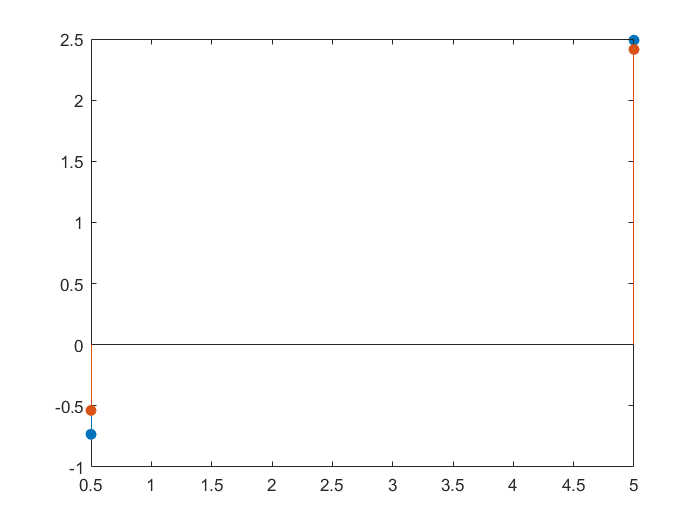

hold on
stem(splineCal(:,1),splineCal(:,2),'filled')

% blue one is the polyCalculation in 0.5,5
% orange one is the splineCalculation in 0.5,5
% you can see the differences and enjoy!
%splineCalculate = [0.5,before(0.5);5,after(5)]
%stem(splineCalculate,'filled')

## now for the second input ( input2 )

figure
plot(domain,log(domain)/log(2),'g*')
hold on
splines2 = splineDraw(input2);

dimension = 7

hold on
syms x
f2(x) = giveMeNewtonPolynomial(input2);

deltaMatrix =     1.0000         0         0         0         0         0         0         0
    1.5000    0.5850    1.1699         0         0         0         0         0
    2.0000    1.0000    0.8301   -0.3399         0         0         0         0
    2.5000    1.3219    0.6439   -0.1862    0.1024         0         0         0
    3.0000    1.5850    0.5261   -0.1178    0.0456   -0.0284         0         0
    3.5000    1.8074    0.4448   -0.0813    0.0243   -0.0106    0.0071         0
    4.0000    2.0000    0.3853   -0.0595    0.0145   -0.0049    0.0023   -0.0016


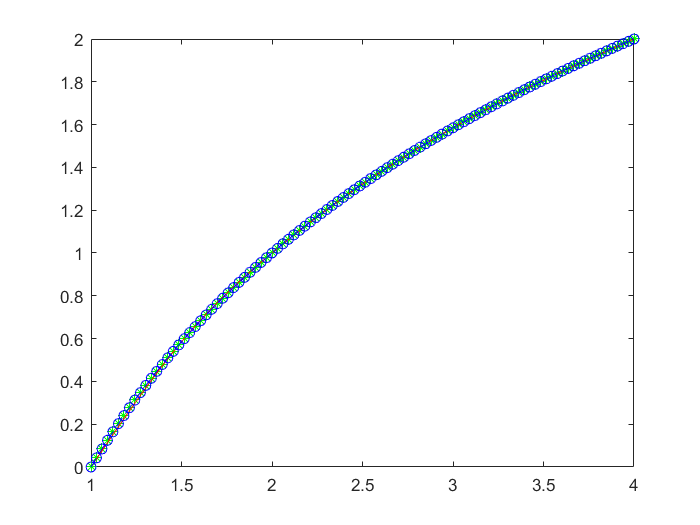

plot(domain,f2(domain),'b--o');

% green is for the main function
% red is for the spline approximation
% blue is for the polynomial approximation 

# `part D for second input(input2)`

`calculate the function in x = 0.5 & x = 5;`

% calculation via polynomial 
figure
polyCal2 = [0.5,f(0.5);5,f(5)]

$$polyCal2 = \left(\begin{array}{cc} \frac{1}{2} & -\frac{844211458418370437}{1152921504606846976}\\ 5 & \frac{44859905450327617}{18014398509481984} \end{array}\right)$$

stem(polyCal2(:,1),polyCal2(:,2),'filled');
hold on 
syms x
before2(x) = splines2(1,1);
after2(x) = splines2(3,1);
splineCal2 = [0.5,before2(0.5);5,after2(5)]

$$splineCal2 = \left(\begin{array}{cc} \frac{1}{2} & -\frac{21075495202188099}{36028797018963968}\\ 5 & \frac{288378259513540607}{144115188075855872} \end{array}\right)$$

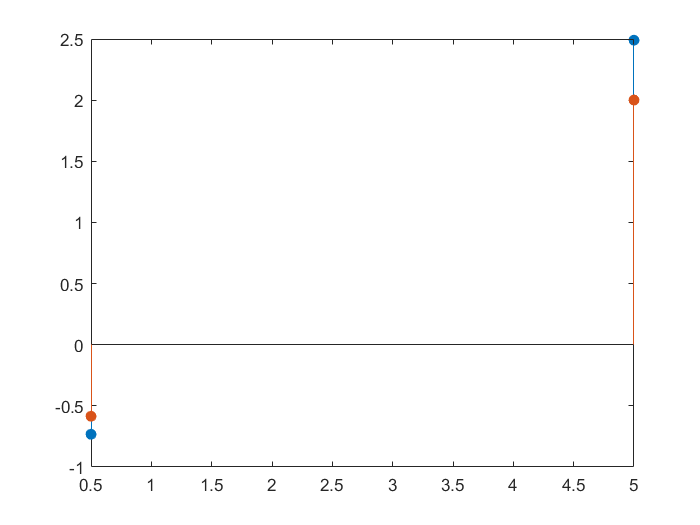

hold on
stem(splineCal2(:,1),splineCal2(:,2),'filled')

% blue one is the polyCalculation in 0.5,5
% orange one is the splineCalculation in 0.5,5
% you can see the differences and enjoy!
%splineCalculate = [0.5,before(0.5);5,after(5)]
%stem(splineCalculate,'filled')

# Second Question

input(:,1) = [0;1;4;9;16;25;36;49;64];
input(:,2) = [0;1;2;3;4;5;6;7;8];
% first ploting data via sqrt function
figure
xDomain = linspace(0,64,100);
plot(xDomain,sqrt(xDomain),'r--o');
syms x
poly(x) = giveMePolywithDegree(input,8); % 8 as an degree

hold on 
plot(xDomain,poly(xDomain),'b--*');
hold on
splinefuncs = splineDraw(input)

dimension = 9

$$splinefuncs = \left(\begin{array}{c} \frac{2447306734017597\,x}{2251799813685248}-\frac{1564055362658791\,x^{3}}{18014398509481984}\\ \frac{202447380058821\,x}{4503599627370496}+\frac{893944702131563\,{\left(x-1\right)}^{3}}{288230376151711744}+\frac{1564055362658791\,{\left(x-4\right)}^{3}}{54043195528445952}+\frac{7820276813293955}{4503599627370496}\\ \frac{4832540679827317\,x}{18014398509481984}-\frac{1002464818387405\,{\left(x-4\right)}^{3}}{1152921504606846976}-\frac{2681834106394689\,{\left(x-9\right)}^{3}}{1441151880758558720}+\frac{1563533563551625}{2251799813685248}\\ \frac{8052433512450965\,x}{72057594037927936}+\frac{3555964543624235\,{\left(x-9\right)}^{3}}{258254417031933722624}+\frac{5012324091937025\,{\left(x-16\right)}^{3}}{8070450532247928832}+\frac{159051123033282275}{72057594037927936}\\ \frac{8385805188415737\,x}{72057594037927936}-\frac{563375398444079\,{\left(x-16\right)}^{3}}{10376293541461622784}-\frac{3555964543624235\,{\left(x-25\right)}^{3}}{332041393326771929088}+\frac{9593433027116837}{4503599627370496}\\ \frac{6273147444250441\,x}{72057594037927936}-\frac{159676601594745\,{\left(x-25\right)}^{3}}{12682136550675316736}+\frac{563375398444079\,{\left(x-36\right)}^{3}}{12682136550675316736}+\frac{207719810534112031}{72057594037927936}\\ \frac{694325342134261\,x}{9007199254740992}-\frac{5570880070830817\,{\left(x-36\right)}^{3}}{479615345916448342016}+\frac{159676601594745\,{\left(x-49\right)}^{3}}{14987979559889010688}+\frac{7314576556163905}{2251799813685248}\\ \frac{4640630225453407\,x}{72057594037927936}+\frac{5570880070830817\,{\left(x-64\right)}^{3}}{553402322211286548480}+\frac{279460417874405457}{72057594037927936} \end{array}\right)$$

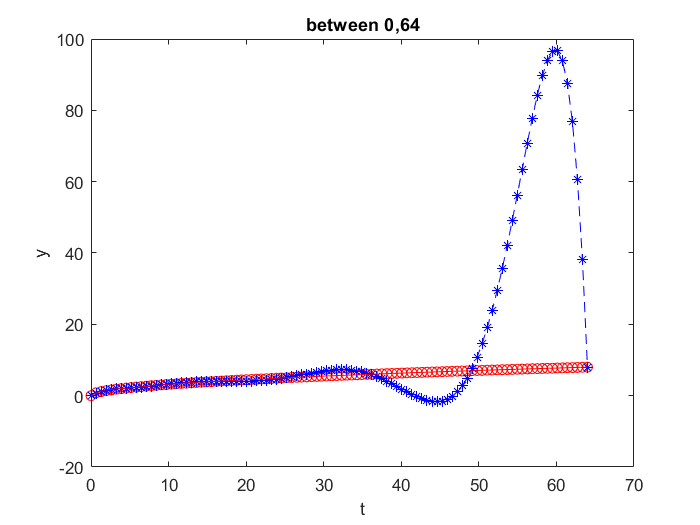

title('between 0,64');
xlabel('t')
ylabel('y')

% blue for the polynomial with 8 degree
% red for the main sqrt function (with stars)
% green for spline (with bubles)

% lets see between 0,1

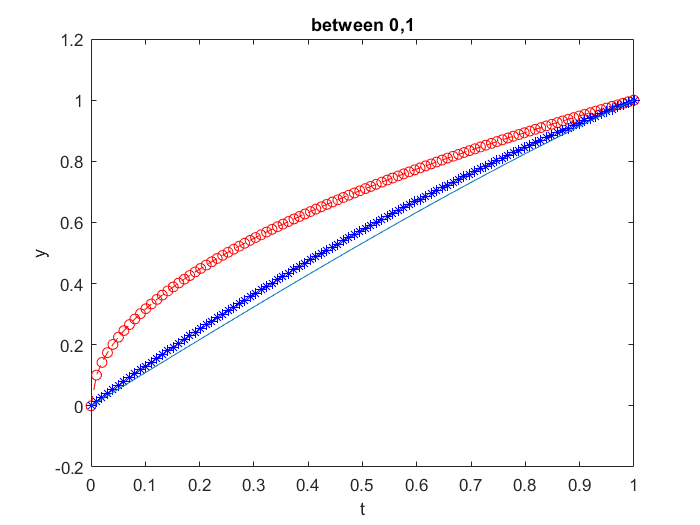

figure
xZeroOne = linspace(0,1,100);
plot(xZeroOne,sqrt(xZeroOne),'r--o');
hold on 
plot(xZeroOne,poly(xZeroOne),'b--*');
hold on
syms x
mySpline(x) = splinefuncs(1,1);
plot(xZeroOne,mySpline(xZeroOne));
title('between 0,1');
xlabel('t');
ylabel('y');

% blue for the polynomial with 8 degree
% red for the main sqrt function (with stars)
% green for spline (with bubles)

## **AskedQuestions Answers :**

**c)Which of the two interpolants is more accurate over most of the domain?**

`As we see in the first graph we conclude that the spline polynomial(the green one) is more accurate over most`

`of the domain.`

**d) Which of the two interpolants is more accurate between 0 and 1? **

`As we see in the second graph we conclude that the polynomial of degree 8 (the blue one) is more accurate `

`between 0,1;`

# Third Question

`first part`

xVec = [1.02;0.95;0.87;0.77;0.67;0.56;0.44;0.30;0.16;0.01];
yVec = [0.39;0.32;0.27;0.22;0.18;0.15;0.13;0.12;0.13;0.15];
inputVec = [xVec,yVec]

inputVec =     1.0200    0.3900
    0.9500    0.3200
    0.8700    0.2700
    0.7700    0.2200
    0.6700    0.1800
    0.5600    0.1500
    0.4400    0.1300
    0.3000    0.1200
    0.1600    0.1300
    0.0100    0.1500


coefs = leastSquarecoef(inputVec,0)  % second argument means that i use pivoting during the solution or not

nonLinMat =     0.1521    0.3978    1.0200    0.3900    1.0000
    0.1024    0.3040    0.9500    0.3200    1.0000
    0.0729    0.2349    0.8700    0.2700    1.0000
    0.0484    0.1694    0.7700    0.2200    1.0000
    0.0324    0.1206    0.6700    0.1800    1.0000
    0.0225    0.0840    0.5600    0.1500    1.0000
    0.0169    0.0572    0.4400    0.1300    1.0000
    0.0144    0.0360    0.3000    0.1200    1.0000
    0.0169    0.0208    0.1600    0.1300    1.0000
    0.0225    0.0015    0.0100    0.1500    1.0000


rightMat =     1.0404
    0.9025
    0.7569
    0.5929
    0.4489
    0.3136
    0.1936
    0.0900
    0.0256
    0.0001


answer =    -2.6356
    0.1436
    0.5514
    3.2229
   -0.4329


coefs =    -2.6356
    0.1436
    0.5514
    3.2229
   -0.4329



a = coefs(1,1);
b = coefs(2,1);
c = coefs(3,1);
d = coefs(4,1);
e = coefs(5,1);

syms x
f(x) = ((-(b*x+d) + sqrt((b*x+d)^2 - 4*a*(c*x+e-x^2)))/(2*a))

$$f(x) = \frac{1293849788849275\,x}{47479207785316864}-\frac{17592186044416\,\sqrt{\frac{230301637992935609123515945749\,x}{39614081257132168796771975168}+{\left(\frac{1293849788849275\,x}{9007199254740992}+\frac{7257416452864685}{2251799813685248}\right)}^{2}-\frac{92732827705697\,x^{2}}{8796093022208}-\frac{11299393480188310305422450935}{2475880078570760549798248448}}}{92732827705697}+\frac{7257416452864685}{11869801946329216}$$

g(x) = ((-(b*x+d) - sqrt((b*x+d)^2 - 4*a*(c*x+e-x^2)))/(2*a))

$$g(x) = \frac{1293849788849275\,x}{47479207785316864}+\frac{17592186044416\,\sqrt{\frac{230301637992935609123515945749\,x}{39614081257132168796771975168}+{\left(\frac{1293849788849275\,x}{9007199254740992}+\frac{7257416452864685}{2251799813685248}\right)}^{2}-\frac{92732827705697\,x^{2}}{8796093022208}-\frac{11299393480188310305422450935}{2475880078570760549798248448}}}{92732827705697}+\frac{7257416452864685}{11869801946329216}$$

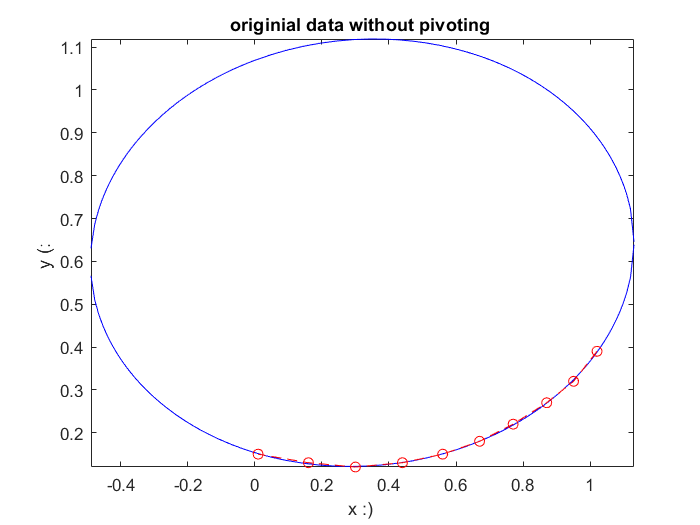

figure
fplot(x,f(x),'b')
hold on 
fplot(x,g(x),'b')
hold on
plot(inputVec(:,1),inputVec(:,2),'r--o')
title('originial data without pivoting ')
xlabel('x :) ')
ylabel('y (: ')

`second part`

% In general, you can generate N random numbers in the interval (a,b) with the formula r = a + (b-a).*rand(N,1).
randNum = -0.005 + (0.01).*rand(10,1);
secondInput = inputVec;
secondInput = [secondInput(:,1) + randNum , secondInput(:,2) + randNum]

secondInput =     1.0166    0.3866
    0.9547    0.3247
    0.8746    0.2746
    0.7699    0.2199
    0.6730    0.1830
    0.5564    0.1464
    0.4392    0.1292
    0.3042    0.1242
    0.1629    0.1329
    0.0146    0.1546


secondCoefs = leastSquarecoef(secondInput,0) % second argument means that i use pivoting during the solution or not

nonLinMat =     0.1494    0.3930    1.0166    0.3866    1.0000
    0.1054    0.3100    0.9547    0.3247    1.0000
    0.0754    0.2401    0.8746    0.2746    1.0000
    0.0483    0.1693    0.7699    0.2199    1.0000
    0.0335    0.1232    0.6730    0.1830    1.0000
    0.0214    0.0815    0.5564    0.1464    1.0000
    0.0167    0.0568    0.4392    0.1292    1.0000
    0.0154    0.0378    0.3042    0.1242    1.0000
    0.0177    0.0217    0.1629    0.1329    1.0000
    0.0239    0.0023    0.0146    0.1546    1.0000


rightMat =     1.0334
    0.9115
    0.7649
    0.5927
    0.4529
    0.3096
    0.1929
    0.0925
    0.0265
    0.0002


answer =    -1.5643
   -0.3135
    0.6492
    3.0530
   -0.4461


secondCoefs =    -1.5643
   -0.3135
    0.6492
    3.0530
   -0.4461



a = secondCoefs(1,1);
b = secondCoefs(2,1);
c = secondCoefs(3,1);
d = secondCoefs(4,1);
e = secondCoefs(5,1);

%*******************
% now i wanna draw both main inputs and it's ellipse and then i wanna draw the second inputs (those with randoms ...) with its ellipse.
%*******************

% first I draw the main inputs ...
% **********************************
figure
fplot(x,f(x),'b')
hold on 
fplot(x,g(x),'b')
hold on
plot(inputVec(:,1),inputVec(:,2),'r--o')

syms x
f1(x) = ((-(b*x+d) + sqrt((b*x+d)^2 - 4*a*(c*x+e-x^2)))/(2*a))

$$f1(x) = \frac{6874836125044631}{7045043515535695}-\frac{2251799813685248\,\sqrt{\frac{41194834665146727247288946600605\,x}{10141204801825835211973625643008}+{\left(\frac{5647585337180827\,x}{18014398509481984}-\frac{6874836125044631}{2251799813685248}\right)}^{2}-\frac{7045043515535695\,x^{2}}{1125899906842624}-\frac{7076616767305444255170439783575}{2535301200456458802993406410752}}}{7045043515535695}-\frac{5647585337180827\,x}{56360348124285560}$$

g1(x) = ((-(b*x+d) - sqrt((b*x+d)^2 - 4*a*(c*x+e-x^2)))/(2*a))

$$g1(x) = \frac{2251799813685248\,\sqrt{\frac{41194834665146727247288946600605\,x}{10141204801825835211973625643008}+{\left(\frac{5647585337180827\,x}{18014398509481984}-\frac{6874836125044631}{2251799813685248}\right)}^{2}-\frac{7045043515535695\,x^{2}}{1125899906842624}-\frac{7076616767305444255170439783575}{2535301200456458802993406410752}}}{7045043515535695}-\frac{5647585337180827\,x}{56360348124285560}+\frac{6874836125044631}{7045043515535695}$$

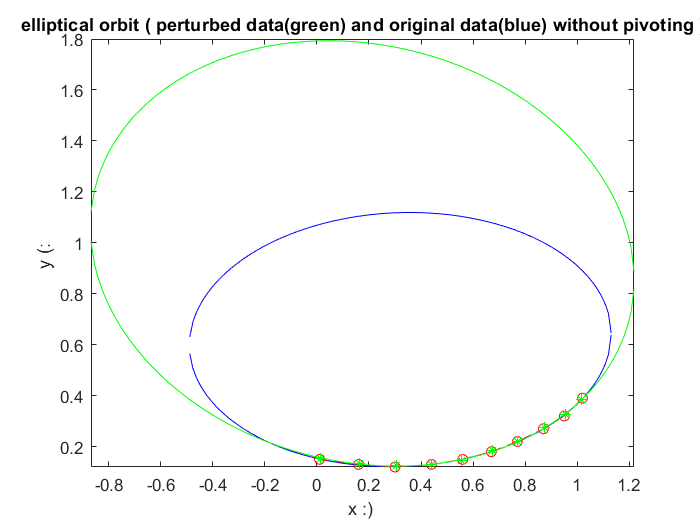

fplot(x,f1(x),'g')
hold on 
fplot(x,g1(x),'g')
hold on
plot(secondInput(:,1),secondInput(:,2),'g*')
title('elliptical orbit ( perturbed data(green) and original data(blue) without pivoting )')
xlabel('x :) ')
ylabel('y (: ')

% green on is the input via randoms
% and the blue one is the main inputs

**Asked Questions's answers :**

 `What effect does this difference have on the plot of the orbit? Can you explain this behavior? `

`as you see in the graph you would consider that just a little differences in main points causes that`

`the best least square ellipse gone the points changes sharply ( BLUE --> GREEN )`

`but why?`

`the answer is here`

`as you know the little changes in the coordinates causes differences in the convexity of ellipse `

`and so little changes in coordinates causes differences in convexity that it itself causes that the main`

`parameters of the ellipse such as semi-minor axis ... semi-major axis ... focus changes sharply and`

`it causes drawn graph changes noticeably :)!!!`

`third part`

`solve the equations via pivoting ...`

dimension = 10;
xVec = [1.02;0.95;0.87;0.77;0.67;0.56;0.44;0.30;0.16;0.01];
yVec = [0.39;0.32;0.27;0.22;0.18;0.15;0.13;0.12;0.13;0.15];
inputVec = [xVec,yVec]

inputVec =     1.0200    0.3900
    0.9500    0.3200
    0.8700    0.2700
    0.7700    0.2200
    0.6700    0.1800
    0.5600    0.1500
    0.4400    0.1300
    0.3000    0.1200
    0.1600    0.1300
    0.0100    0.1500


coefs = leastSquarecoef(inputVec,1)  % second argument means that i use pivoting during the solution or not

nonLinMat =     0.1521    0.3978    1.0200    0.3900    1.0000
    0.1024    0.3040    0.9500    0.3200    1.0000
    0.0729    0.2349    0.8700    0.2700    1.0000
    0.0484    0.1694    0.7700    0.2200    1.0000
    0.0324    0.1206    0.6700    0.1800    1.0000
    0.0225    0.0840    0.5600    0.1500    1.0000
    0.0169    0.0572    0.4400    0.1300    1.0000
    0.0144    0.0360    0.3000    0.1200    1.0000
    0.0169    0.0208    0.1600    0.1300    1.0000
    0.0225    0.0015    0.0100    0.1500    1.0000


rightMat =     1.0404
    0.9025
    0.7569
    0.5929
    0.4489
    0.3136
    0.1936
    0.0900
    0.0256
    0.0001


answer =    -2.6356
    0.1436
    0.5514
    3.2229
   -0.4329


coefs =    -2.6356
    0.1436
    0.5514
    3.2229
   -0.4329



a = coefs(1,1);
b = coefs(2,1);
c = coefs(3,1);
d = coefs(4,1);
e = coefs(5,1);

syms x
f2(x) = ((-(b*x+d) + sqrt((b*x+d)^2 - 4*a*(c*x+e-x^2)))/(2*a))

$$f2(x) = \frac{5175399155356893\,x}{189916831141122656}-\frac{1125899906842624\,\sqrt{\frac{7369652415770590681110666711003\,x}{1267650600228229401496703205376}+{\left(\frac{5175399155356893\,x}{36028797018963968}+\frac{7257416452864797}{2251799813685248}\right)}^{2}-\frac{5934900973160083\,x^{2}}{562949953421312}-\frac{46282315694821295825389560415381}{10141204801825835211973625643008}}}{5934900973160083}+\frac{7257416452864797}{11869801946320166}$$

g2(x) = ((-(b*x+d) - sqrt((b*x+d)^2 - 4*a*(c*x+e-x^2)))/(2*a))

$$g2(x) = \frac{5175399155356893\,x}{189916831141122656}+\frac{1125899906842624\,\sqrt{\frac{7369652415770590681110666711003\,x}{1267650600228229401496703205376}+{\left(\frac{5175399155356893\,x}{36028797018963968}+\frac{7257416452864797}{2251799813685248}\right)}^{2}-\frac{5934900973160083\,x^{2}}{562949953421312}-\frac{46282315694821295825389560415381}{10141204801825835211973625643008}}}{5934900973160083}+\frac{7257416452864797}{11869801946320166}$$

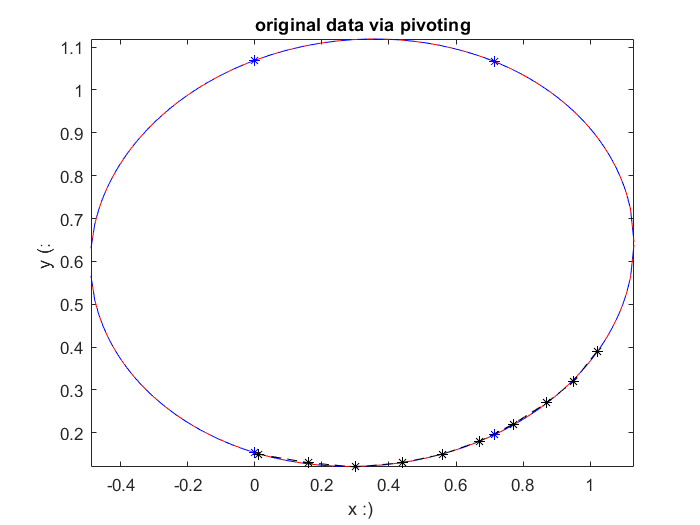

figure
fplot(x,f(x),'r')
hold on 
fplot(x,g(x),'r')
hold on
fplot(x,f2(x),'b--*')
hold on 
fplot(x,g2(x),'b--*')
hold on
plot(inputVec(:,1),inputVec(:,2),'black--*')
title('original data via pivoting')
xlabel('x :) ')
ylabel('y (: ')

% blue is origin data via pivoting
% red is origin data without pivoting

% In general, you can generate N random numbers in the interval (a,b) with the formula r = a + (b-a).*rand(N,1).
%randNum = -0.005 + (0.01).*rand(10,1);
%secondInput = inputVec;
%secondInput = [secondInput(:,1) + randNum , secondInput(:,2) + randNum]
secondCoefs = leastSquarecoef(secondInput,1) % second argument means that i use pivoting during the solution or not

nonLinMat =     0.1494    0.3930    1.0166    0.3866    1.0000
    0.1054    0.3100    0.9547    0.3247    1.0000
    0.0754    0.2401    0.8746    0.2746    1.0000
    0.0483    0.1693    0.7699    0.2199    1.0000
    0.0335    0.1232    0.6730    0.1830    1.0000
    0.0214    0.0815    0.5564    0.1464    1.0000
    0.0167    0.0568    0.4392    0.1292    1.0000
    0.0154    0.0378    0.3042    0.1242    1.0000
    0.0177    0.0217    0.1629    0.1329    1.0000
    0.0239    0.0023    0.0146    0.1546    1.0000


rightMat =     1.0334
    0.9115
    0.7649
    0.5927
    0.4529
    0.3096
    0.1929
    0.0925
    0.0265
    0.0002


answer =    -1.5643
   -0.3135
    0.6492
    3.0530
   -0.4461


secondCoefs =    -1.5643
   -0.3135
    0.6492
    3.0530
   -0.4461



a = secondCoefs(1,1);
b = secondCoefs(2,1);
c = secondCoefs(3,1);
d = secondCoefs(4,1);
e = secondCoefs(5,1);

%*******************
% now i wanna draw both main inputs and it's ellipse and then i wanna draw the second inputs (those with randoms ...) with its ellipse.
%*******************

% first I draw the main inputs ...
% **********************************

figure
fplot(x,f(x),'black')
hold on 
fplot(x,g(x),'black')
hold on
plot(secondInput(:,1),secondInput(:,2),'black--*')

syms x
f3(x) = ((-(b*x+d) + sqrt((b*x+d)^2 - 4*a*(c*x+e-x^2)))/(2*a))

$$f3(x) = \frac{2291612041681353}{2348347838525978}-\frac{1125899906842624\,\sqrt{\frac{1287338583291946615253393549355\,x}{316912650057057350374175801344}+{\left(\frac{5647585337086403\,x}{18014398509481984}-\frac{6874836125044059}{2251799813685248}\right)}^{2}-\frac{3522521757788967\,x^{2}}{562949953421312}-\frac{28306467069376065095544734648667}{10141204801825835211973625643008}}}{3522521757788967}-\frac{5647585337086403\,x}{56360348124623472}$$

g3(x) = ((-(b*x+d) - sqrt((b*x+d)^2 - 4*a*(c*x+e-x^2)))/(2*a))

$$g3(x) = \frac{1125899906842624\,\sqrt{\frac{1287338583291946615253393549355\,x}{316912650057057350374175801344}+{\left(\frac{5647585337086403\,x}{18014398509481984}-\frac{6874836125044059}{2251799813685248}\right)}^{2}-\frac{3522521757788967\,x^{2}}{562949953421312}-\frac{28306467069376065095544734648667}{10141204801825835211973625643008}}}{3522521757788967}-\frac{5647585337086403\,x}{56360348124623472}+\frac{2291612041681353}{2348347838525978}$$

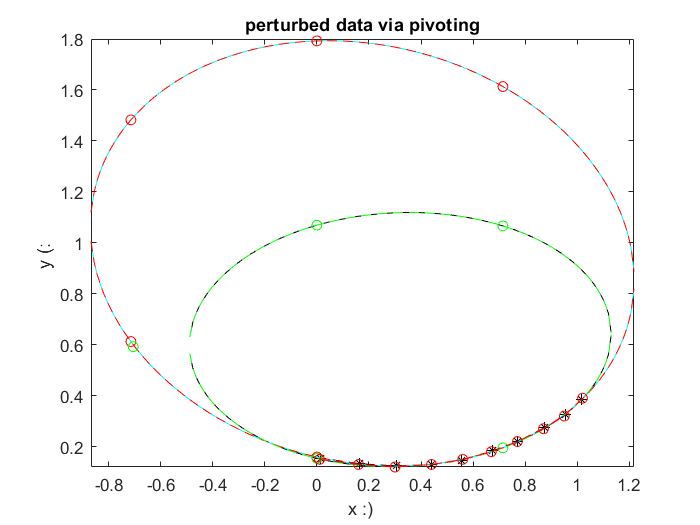

hold on
fplot(x,f3(x),'cyan')
hold on 
fplot(x,g3(x),'cyan')
hold on
fplot(x,f1(x),'red--o')
hold on 
fplot(x,g1(x),'red--o')
hold on
fplot(x,f2(x),'green--o')
hold on 
fplot(x,g2(x),'green--o')
hold on
plot(inputVec(:,1),inputVec(:,2),'r--o')
title('perturbed data via pivoting')
xlabel('x :) ')
ylabel('y (: ')

% cyan one is perturbed data via pivoting
% red one is the perturbed data without pivoting
% black one is the main origin data without pivoting
% green one is the main origin data via pivoting
% i wanna draw all graphs all togather

`Asked Questions`

`1.Which solution would you regard as better: one that fits the data more closely, or one that is less sensitive to small perturbations in the data? Why? `

`since matlab itself implements algorithms with high precision when we use pivoting the answer doesn't`

`changes sharply but ... the AskedQuestion's answer is :`

`I prefer pivoting and putting the data more closely`

`because as you see in the graphs... little changes in data causes that the ellipse gone the points `

`changes sharply so i prefer to use the one with more precision... and we also know that pivoting increases the`

`precision so I chose That :) !`

`I Also used pivoting in both dimensions ... vertical and Horizontal ...`

function f = leastSquarecoef(inputVec,pivot)
mySize = size(inputVec);
dimension = mySize(1,1);
xVec = inputVec(:,1);
yVec = inputVec(:,2);

nonLinMat = zeros(dimension,5);
rightMat = zeros(dimension,1);

for i=1:dimension
    nonLinMat(i,:) = [yVec(i,1)^2,xVec(i,1)*yVec(i,1),xVec(i,1),yVec(i,1),1];
    rightMat(i,1) = xVec(i,1)^2;
end

nonLinMat
rightMat

% now lets solve the equation :
% nonLinMat * [a;b;c;d;e;f] = rightMat
% if we have Ax = B
% then we would have the answer matrix : inv(transpose(A)*A) * (transpose(A)*B)

if(pivot)
answer = GAUSS_ELIM(transpose(nonLinMat) * nonLinMat , transpose(nonLinMat) * rightMat)
else
answer = (transpose(nonLinMat)*nonLinMat)\(transpose(nonLinMat)*rightMat)
end

% remember the function : ay^2 + bxy + cx + dy + e = x^2
% and as you know the answer are : 
% secondRoot = ((-(b*x+d) + sqrt((b*x+d)^2 - 4*a*(c*x+e-x^2)))/(2*a))
% firstRoot  = ((-(b*x+d) - sqrt((b*x+d)^2 - 4*a*(c*x+e-x^2)))/(2*a))

a = answer(1,1);
b = answer(2,1);
c = answer(3,1);
d = answer(4,1);
e = answer(5,1);

f = [a;b;c;d;e];

end



function f = giveMePolywithDegree(input,degree)
Mysize = size(input);
m = Mysize(1,1);
sigmaCalculater = zeros(2*degree + 1,1);
sigmaCalculater(1,1) = m;
for power = 1:2*degree
    sum = 0;
    for i=1:m
        sum = sum + input(i,1)^power;
    end
    sigmaCalculater(power + 1,1) = sum;
end

bigMatrixCoef = zeros(degree + 1,degree);
yMat = zeros(degree+1,1);

for i=1:degree + 1
    for j = 1:degree + 1
        bigMatrixCoef(i,j) = sigmaCalculater(i+j-1,1);
    end  
end

for i=1:degree+1
    sum = 0;
    for j=1:m
    sum = sum + (input(j,1)^(i-1))*(input(j,2));
    end
    yMat(i,1) = sum;
end
theCoefs = mldivide(bigMatrixCoef,yMat);
syms x
f(x) = 0*x;
for i=1:degree+1
    f(x) = f(x) + theCoefs(i,1)*(x^(i-1));
end
f = f(x);
end



function f = giveMeNewtonPolynomial(inputValues)
mySize = size(inputValues);
dimension = mySize(1,1);
deltaMatrix  = zeros(dimension,dimension + 1);
deltaMatrix(:,1:2) = inputValues;
for i = 3 : dimension + 1
        temp = 1;
        for k = i-1 : dimension
            deltaMatrix(k,i) = (deltaMatrix(k,i-1) - deltaMatrix(k-1,i-1))/(inputValues(temp + i - 2,1) - inputValues(temp,1));
            temp = temp + 1;
        end
end
deltaMatrix
syms x
f(x) = inputValues(1,2) * (x ^ 0);
miniDelta = 1;
for  i=1:dimension-1
miniDelta = (miniDelta)*(x - inputValues(i,1));
f(x) = f(x) + deltaMatrix(i+1,i+2) * miniDelta;
end
f = f(x);
end



%{
  Title: Gaussian Elimination Method with Pivoting for Solving a Linear System
  Description: This function solves a linear system Ax=b using the Gaussian
  elimination method with pivoting. The algorithm is outlined below:
    1) Initialize a permutation vector r = [1, 2,...,n] where r(i)
    corresponds to row i in A.
    2) For k = 1,...,n-1 find the largest (in absolute value) element among
    a(r(k),k),a(r(k+1),k),...,a(r(n),k).
    3) Assume r(j,k) is the largest element. Switch r(j) and r(k).
    4) For i=1,...,k-1,k+1,...,n calculate:
            zeta = a(r(i),k) / a(r(k),k)
    5) For j=k,...,n calculate:
            a(r(i),j)=a(r(i),j)-a(r(k),j)*zeta;
            b(r(i)) = b(r(i))-b(r(k))*zeta
    6) Steps 1 through 6 has effectively diagonalized A.
    7) Each element in the solution vector is:
            x(r(i)) = b(i)/a(i,i);             
  Input parameters: A = n by n matrix in standard Matlab notation
                    b = n by 1 right-hand vector
  Output: x = computed solution
%}

function x = GAUSS_ELIM(A, b)
%% Create permutation vector
n = size(A, 1);  % Size of input matrix
r = zeros(n, 1); % Initialize permutation vector
for i = 1 : 1 : n    
   r(i) = i;
end
%% Apply Gaussian elimination and rearrange permutation vector
x = zeros(n, 1); % Initialize solution vector
for k = 1 : 1 : n % Go through each element in permutation vector    
    % Compare each element in r(k)th column for the max
    max = abs(A(r(k), r(k)));    
    max_pos = k;    
    for l = k : 1 : n        
        if abs(A(r(l), r(k))) > max            
            max = abs(A(r(l), r(k)));            
            max_pos = l;            
        end
    end
    % Switch the kth r-vector element with max r-vector element
    temp_r = r;
    r(k) = temp_r(max_pos);
    r(max_pos) = temp_r(k);
    % Eliminate A-vector elements in r(k)th column below r(k)th row        
    for i = 1 : 1 : n
        if i ~= k
            zeta = A(r(i), k) / A(r(k), k);
            for j = k : 1 : n
                A(r(i), j) = A(r(i), j) - A(r(k), j) * zeta;                       
            end
            b(r(i)) = b(r(i)) - b(r(k)) * zeta;
        end
    end
end
% Compute the solution frpm the diagonalized A-matrix
for i = 1 : 1 : n
    x(i) = b(r(i)) / A(r(i), i);
end
end




function splineFunctions = splineDraw(inputVectors)

inputSize = size(inputVectors);
dimension = inputSize(1,1);
Hvectors = zeros(dimension-1,1);
%Mvectors also
Dvectors = zeros(dimension-1,1);
Cvectors = zeros(dimension-1,1);
for i=1:dimension-1
    Hvectors(i,1) = inputVectors(i+1,1) - inputVectors(i,1);
end
Msolver = zeros(dimension,dimension);
fValues = zeros(dimension,1);
fValues(1,1) = 0;
fValues(dimension,1) = 0;
Msolver(1,1) = 1;
Msolver(dimension,dimension) = 1;
j = 0 ;
for i=1:dimension-2  
       Msolver(i+1,j+1) = Hvectors(i,1); 
       Msolver(i+1,j+2) = 2*(Hvectors(i,1) + Hvectors(i+1,1));
       Msolver(i+1,j+3) = Hvectors(i+1,1);
       j = j + 1;
end
for i = 2:dimension-1
    fValues(i,1) = (inputVectors(i+1,2) - inputVectors(i,2))/(inputVectors(i+1,1) -inputVectors(i,1)) - (inputVectors(i,2) - inputVectors(i-1,2))/(inputVectors(i,1) - inputVectors(i-1,1));
end
Mvectors = mldivide(Msolver,fValues);
for i=1:dimension-1
   Dvectors(i,1) = inputVectors(i,2) - (Hvectors(i,1)^2) * Mvectors(i,1);
   Cvectors(i,1) = (inputVectors(i + 1,2) - inputVectors(i,2))/Hvectors(i,1) + Hvectors(i,1) * (Mvectors(i,1) - Mvectors(i+1,1));
end
dimension
for i=1:dimension-1
% s_i(x_i) = ((-(x-xi)^3)/hi)*mi +(((x-xi)^3)/hi)mi+1 + ci(x-xi) + di; i = 1;    
syms x
s(x) = -(((x-inputVectors(i+1,1))^3)/Hvectors(i,1))*Mvectors(i,1) + (((x-inputVectors(i,1))^3)/Hvectors(i,1))*Mvectors(i+1,1) + Cvectors(i,1)*(x-inputVectors(i,1)) + Dvectors(i,1);
if(i == 1)
    splineFunctions = s(x);
else
    splineFunctions = [splineFunctions;s(x)];
end    
data = inputVectors(i,1):0.001:inputVectors(i+1,1);
plot(data,s(data),'r')
hold on
end
ZiMatrix_second_derivative = 6 * Mvectors;

# You can also calculate Ai,Bi and Ci by eliminating the % tags! ( just remove the %s! )

%% now i create the Ai,Bi,Ci which we have s(x) = yi + (x-ti)[Ci + (x-ti)[ Bi + (x-ti)Ai]]
% Bimatrix = ZiMatrix_second_derivative(1:dimension-1,1)/2;
% for i=1:dimension-1
% Aimatrix = vpa((ZiMatrix_second_derivative(i+1) - ZiMatrix_second_derivative(i))/(6 * Hvectors(i,1)));
% Cimatrix = vpa((inputVectors(i+1,2)-inputVectors(i,2)/(Hvectors(i,1))) + ((1/3)*(Hvectors(i,1) * ZiMatrix_second_derivative(i,1))) + (-1/6)*Hvectors(i,1)*ZiMatrix_second_derivative(i+1,1));
% end
end
% amir
